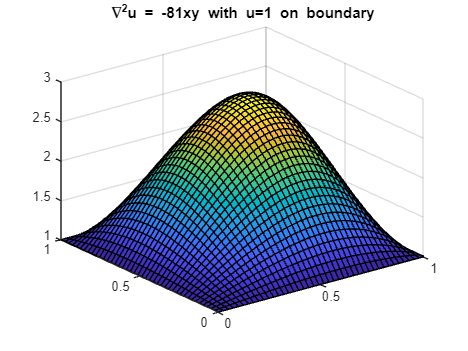

N = 40; 
[X, Y] = meshgrid(linspace(0,1,N+2));

% Define the specific source term for your problem
f_vals = -81 .* X .* Y; 

% Call the function
U = poisson_solver_custom(N, f_vals);

% Plot results
surf(X, Y, U);
title('\nabla^2u = -81xy with u=1 on boundary');


function U = poisson_solver_custom(N, f)
    h = 1/(N+1);
    % Start with 1s to satisfy u(boundary) = 1
    U = ones(N+2); 
    tol = 1e-6;
    max_iter = 10000;
    
    for iter = 1:max_iter
        U_old = U;
        for i = 2:N+1
            for j = 2:N+1
                U(i,j) = 0.25*(U(i+1,j) + U(i-1,j) + U(i,j+1) + U(i,j-1) - h^2*f(i,j));
            end
        end
        if max(max(abs(U - U_old))) < tol
            break;
        end
    end
end